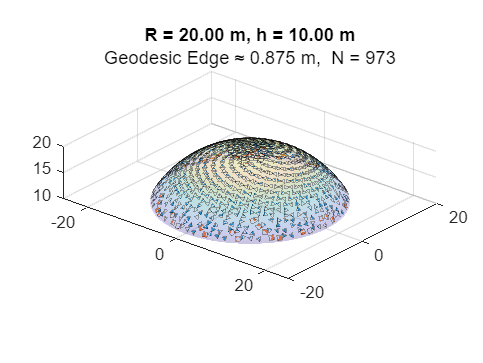

%==========================================================================
% Spherical Dome Tessellation
%
% Description:
%   Generates a tessellation on a spherical cap using quasi-uniform Fibonacci
%   sampling of candidate centers and a Poisson-disk filter in geodesic
%   distance to avoid overlaps. Polygon tiles are built on the tangent plane
%   and radially projected onto the sphere. Coverage is computed with the
%   true spherical area (not a planar approximation).
%
% User Inputs (edit this block):
%   R             - Sphere radius (m), R > 0.
%   h             - Dome height (m), 0 < h <= R.
%   polygonNumber - Number of polygon types: 1 or 2.
%   l1, l2        - Number of sides for polygon types (integers >= 3).
%                   If num_poligonos == 1, l2 is ignored (set l2 = l1).
%   mode          - Size mode:
%                     1 -> control by geodesic EDGE length (a_edge_sph, m)
%                     2 -> control by target number of tiles (N_target)
%   a_edge        - Desired geodesic edge length (m). Used only if mode == 1.
%   N_target      - Approximate target number of tiles. Used only if mode == 2.
%   seed          - RNG seed for reproducible phases/Poisson.
%   safety_fac    - >= 1, minimum separation factor for Poisson filter in angle.
%
% Outputs:
%   - Figure with the dome and tessellated polygons.
%   - Console report with spherical coverage, effective counts, and sizes.
%
% Quick-start examples:
%   % Edge mode:
%   R=1; h=0.4; num_poligonos=2; l1=6; l2=5; mode=1; a_edge_sph=0.12; N_target=[];
%   % Target N mode:
%   R=1; h=0.4; num_poligonos=1; l1=6; l2=l1; mode=2; a_edge_sph=[]; N_target=220;
%==========================================================================

clc; clear; close all;

%% =========================== User Inputs ================================
R             = 20.0; % Sphere radius (m)
h             = 10.0; % Dome height (m), 0 < h <= R
polygonNumber = 2;    % 1 or 2 polygon types
l1            = 3;    % Sides for first polygon (>=3, integer)
l2            = 4;    % Sides for second polygon (>=3, integer). Ignored if num_poligonos==1
mode          = 2;    % 1 = geodesic edge control, 2 = target number of tiles
a_edge        = 0.1;  % Geodesic edge length (m). Used if mode==1
N_target      = 2000; % Target number of tiles (approx). Used if mode==2

% Optional parameters
seed          = 42;      % RNG seed for reproducibility
safety_fac    = 1.00;    % >=1: minimum separation (r1+r2)*safety_fac in angle

%% ===================== Basic Validation =================================
if isempty(R) || isempty(h) || R <= 0 || h <= 0 || h > R
    error('Invalid geometry: require R > 0 and 0 < h <= R.');
end
if ~ismember(polygonNumber, [1 2])
    error('num_poligonos must be 1 or 2.');
end
if isempty(l1) || l1 < 3 || mod(l1, 1) ~= 0
    error('l1 must be an integer >= 3.');
end
if polygonNumber == 2
    if isempty(l2) || l2 < 3 || mod(l2, 1) ~= 0
        error('l2 must be an integer >= 3.');
    end
else
    l2 = l1; % Mirror type if only one polygon family is requested
end
if ~ismember(mode, [1 2])
    error('mode must be 1 (Geodesic edge control) or 2 (target number of tiles).');
end
if mode == 1
    if isempty(a_edge) || a_edge <= 0
        error('a_edge_sph must be > 0 when mode == 1.');
    end
    N_target = [];
else
    if isempty(N_target) || numel(N_target) < 1
        error('N_target must be >= 1 when mode == 2.');
    end
    a_edge = [];
end

rng(seed);

%% ===================== Derived Parameters ================================
phi_max = acos((R - h) / R);   % Polar angle of the cap rim
A_cap   = 2 * pi * R * h;      % Exact spherical cap area

% Conversions: Geodesic edge length -> approximate planar circumradius rc.
% For a planar regular l-gon: rc = a/(2*sin(pi/l)).
% We use the tangent-plane rc and define an angular radius theta_c = rc/R.
if ~isempty(a_edge)
    rc1 = a_edge / (2 * sin(pi / l1));  
        theta1 = rc1 / R;
    rc2 = a_edge / (2 * sin(pi / l2));  
        theta2 = rc2 / R;
    a_edge_eff = a_edge; % Report the requested edge length

    % Estimate number of tiles from mean (planar) polygon area and a packing factor
    A_poly_avg = polyAreaFromRC(l1, rc1); % Planar approximation
    pack_fac   = 0.82;                    % Empirical packing
    N_est      = max(1, ceil(A_cap / (A_poly_avg * pack_fac)));
else
    % Infer edge size from target N using average l and planar area
    l_avg      = round((l1 + l2) / 2);
    pack_fac   = 0.82;
    A_poly_avg = (A_cap / (max(1, N_target) * pack_fac));
    rc_avg     = sqrt(2 * A_poly_avg / (l_avg * sin(2 * pi / l_avg)));
    a_edge_eff = 2 * rc_avg * sin(pi / l_avg);

    rc1 = a_edge_eff / (2 * sin(pi / l1));   theta1 = rc1 / R;
    rc2 = a_edge_eff / (2 * sin(pi / l2));   theta2 = rc2 / R;
    N_est = max(1, round(N_target));
end

% Angular margin to stay within the cap boundary
phi_margin = 1.10 * max(theta1, theta2); % Conservative margin (rad)
phi_eff    = max(0, phi_max - phi_margin);

%% ===================== Center Sampling ==================================
% Generate many candidates on the spherical cap using Fibonacci sampling and
% filter them with a geodesic Poisson-disk to avoid overlaps.
N_candidatos = max(N_est, 200); % Ensure a reasonable pool
cand = fibonacciPoints(N_candidatos, R, phi_eff);

% Alternate polygon types by index (some will be discarded by the filter)
lados_vec0 = repmat([l1; l2], ceil(N_candidatos/2), 1); lados_vec0 = lados_vec0(1:N_candidatos);
theta_vec0 = repmat([theta1; theta2], ceil(N_candidatos/2), 1); theta_vec0 = theta_vec0(1:N_candidatos);

% Poisson filter in geodesic distance between centers
[centros, lados_vec, theta_vec] = poissonGeodesicFilter(cand, lados_vec0, theta_vec0, safety_fac);

% Trim to the approximate target (if too many survived)
if numel(lados_vec) > N_est
    idx       = (1:N_est).';
    centros   = centros(idx, :);
    lados_vec = lados_vec(idx);
    theta_vec = theta_vec(idx);
end
N = size(centros, 1);

%% ===================== REFERENCE DOME GEOMETRY ==========================
% Visual mesh of the spherical cap
Phi   = linspace(0, phi_max, 48);
Theta = linspace(0, 2*pi, 96);
[PhiM, ThetaM] = meshgrid(Phi, Theta);
Xs = R * sin(PhiM) .* cos(ThetaM);
Ys = R * sin(PhiM) .* sin(ThetaM);
Zs = R * cos(PhiM);

% Cap rim (plane z = z0)
z0     = R - h;
r_base = sqrt(max(0, R^2 - z0^2));
tth    = linspace(0, 2*pi, 200);
xb     = r_base * cos(tth);
yb     = r_base * sin(tth);
zb     = z0 * ones(size(tth));

%% ===================== DRAWING ==========================================
figure('Color', 'w'); hold on;
surf(Xs, Ys, Zs, 'FaceAlpha', 0.20, 'EdgeColor', 'none');
fill3(xb, yb, zb, [0 0 0], 'FaceAlpha', 0.08, 'EdgeColor', 'none');

cmap      = lines(2);
N_drawn   = 0;
A_sph_sum = 0;
N1 = 0; N2 = 0;

for i = 1:N
    c       = centros(i, :);
    l       = lados_vec(i);
    theta_c = theta_vec(i); % Approximate angular circumradius

    % Boundary check (with margin)
    phi_c = acos(c(3) / R);
    if phi_c + theta_c > phi_max
        continue;
    end

    % Pseudorandom but deterministic in-plane rotation
    phase = mod(i * goldenAngle, 2*pi / l);

    % Build polygon on tangent plane and project onto sphere
    rc = theta_c * R;                       % Back to tangent-plane length
    P  = polygonOnSphere(c, rc, l, phase, R);

    % Extra safety against crossing the cap plane
    if any(P(:, 3) < z0), continue; end

    % True spherical area of the polygon
    A_poly_sph = sphericalPolygonArea(P, R);

    % Draw polygon
    color_idx = 1 + (l == l2);
    fill3(P(:,1), P(:,2), P(:,3), cmap(color_idx, :), ...
          'FaceAlpha', 0.80, 'EdgeColor', 'k', 'EdgeAlpha', 0.35);

    % Metrics
    A_sph_sum = A_sph_sum + A_poly_sph;
    N_drawn   = N_drawn + 1;
    if l == l1, N1 = N1 + 1; else, N2 = N2 + 1; end
end

axis equal; grid on; view(40, 25);
title(sprintf('R = %.2f m, h = %.2f m', R, h));
subtitle(sprintf('Geodesic Edge ≈ %.3f m,  N = %d', a_edge_eff, N_drawn));


%% ========================= Report ====================================
cover = 100 * (A_sph_sum) / A_cap;  % True spherical coverage

fprintf('\n----- Tessellation Summary -----\n');


----- Tessellation Summary -----


fprintf('R = %.2f m, h = %.2f m (Maximum ϕ = %.2f deg)\n', R, h, rad2deg(phi_max));

R = 20.00 m, h = 10.00 m (Maximum ϕ = 60.00 deg)


fprintf('Types: l₁ = %d sides, l₂ = %d sides\n', l1, l2);

Types: l₁ = 3 sides, l₂ = 4 sides


fprintf('Effective geodesic edge ≈ %.4f m (both types)\n', a_edge_eff);

Effective geodesic edge ≈ 0.8754 m (both types)


fprintf('Drawn tiles: N = %d  (N₁ = %d, N₂ = %d)\n', N_drawn, N1, N2);

Drawn tiles: N = 973  (N₁ = 874, N₂ = 99)


fprintf('Spherical coverage ≈ %.1f %%\n', cover);

Spherical coverage ≈ 19.9 %
